# **Introduction to Engineering and Programming with MATLAB**

**Lab 5 Symbolic Math, Visualization, and Optimization**

Instructor: Yuhong Zhang (Yuhong_zhang1@brown.edu)

**1. Symbolic Math**

**Advanced Algebraic Manipulation**

Simplify complex expressions with assumptions:

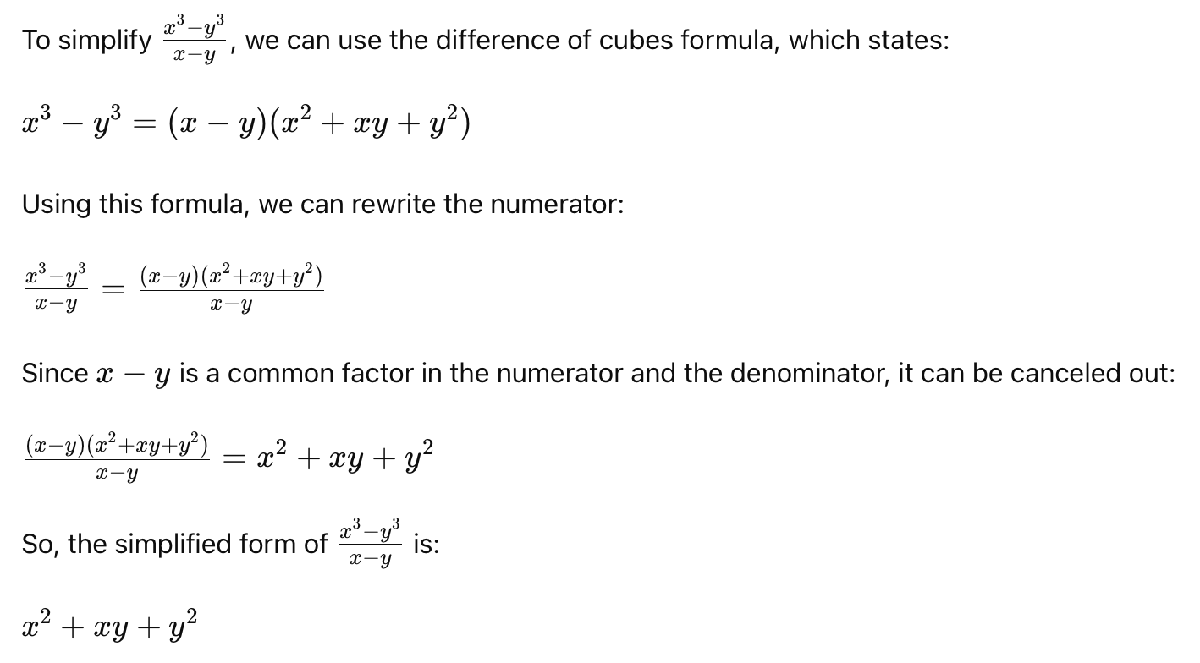

syms x y real;
f = (x^3 - y^3) / (x - y)

$$f = \frac{x^{3}-y^{3}}{x-y}$$

simplified_f = simplify(f)

$$simplified\_f = x^{2}+x\,y+y^{2}$$

**Solving Systems of Equations**

Solve nonlinear systems of equations:

syms x y;
eq1 = x^2 + y^2 == 1

$$eq1 = x^{2}+y^{2}=1$$

eq2 = x^3 - y == 0

$$eq2 = x^{3}-y=0$$

sol = solve([eq1, eq2], [x, y])

sol = struct with fields:
    x: [6×1 sym]
    y: [6×1 sym]


**Differential Equations**

Solve higher-order differential equations:

syms y(t);
Dy = diff(y, t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

D2y = diff(y, t, 2)

$$D2y(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$

eqn = D2y + 3*Dy + 2*y == cos(t)

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=\cos\left(t\right)$$

sol = dsolve(eqn)

$$sol = \frac{\sqrt{10}\,\cos\left(t-\mathrm{atan}\left(3\right)\right)}{10}+C_{1}\,{\mathrm{e}}^{-2\,t}+C_{2}\,{\mathrm{e}}^{-t}$$

**Laplace and Fourier Transforms**

Compute Laplace and inverse Laplace transforms:

syms t s;
f = exp(-2*t) * cos(3*t)

$$f = \cos\left(3\,t\right)\,{\mathrm{e}}^{-2\,t}$$

L = laplace(f, t, s)

$$L = \frac{s+2}{{\left(s+2\right)}^{2}+9}$$

IL = ilaplace(L, s, t)

$$IL = \cos\left(3\,t\right)\,{\mathrm{e}}^{-2\,t}$$

Compute Fourier and inverse Fourier transforms:

syms t w;
f = exp(-t^2);
F = fourier(f, t, w)

$$F = \sqrt{\pi }\,{\mathrm{e}}^{-\frac{w^{2}}{4}}$$

IF = ifourier(F, w, t)

$$IF = {\mathrm{e}}^{-t^{2}}$$

**Vector Calculus**

Perform vector calculus operations like divergence, gradient, and curl:

syms x y z;
F = [x*y, y*z, z*x];
divF = divergence(F, [x, y, z])

$$divF = x+y+z$$

gradF = gradient(sum(F), [x, y, z])

$$gradF = \left(\begin{array}{c} y+z\\ x+z\\ x+y \end{array}\right)$$

curlF = curl(F, [x, y, z])

$$curlF = \left(\begin{array}{c} -y\\ -z\\ -x \end{array}\right)$$

**Integral Transforms and Special Functions**

Use integral transforms and special functions:

syms x;
intTransform = int(exp(-x^2), x, 0, inf);
specialFunc = besselj(1, x);


**2. Visualization**

**3D Surface and Contour Plots**

Create and customize 3D surface and contour plots:

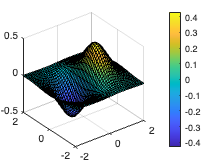

[X, Y] = meshgrid(-2:0.1:2, -2:0.1:2);
Z = X.*exp(-X.^2 - Y.^2);
surf(X, Y, Z);
colorbar;

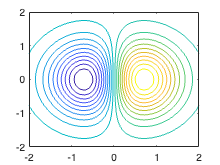

contour(X, Y, Z, 20);

**Vector Field Visualization**

Visualize vector fields with quiver and streamline plots:

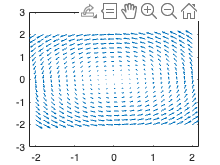

[X, Y] = meshgrid(-2:0.2:2, -2:0.2:2);
U = -Y;
V = X;
quiver(X, Y, U, V);
streamline(X, Y, U, V, [-2 -2], [2 2]);

**Custom Plotting Functions**

Create custom plotting functions for specific data visualizations:

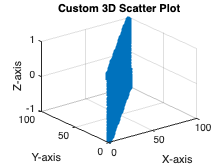

x = 1:0.1:100;
y = 1:0.1:100;
z = sin(x);
lab05funs(x, y, z)

**3. Optimization**

**Advanced Nonlinear Optimization**

Solve complex nonlinear optimization problems with multiple constraints:

f = @(x) x(1)^2 + x(2)^2 + x(3)^2;
nonlcon = @(x) deal([], [x(1)^2 + x(2) - 1; x(2)^2 + x(3) - 1]);
x0 = [0.5, 0.5, 0.5];
options = optimoptions('fmincon', 'Algorithm', 'sqp');
x = fmincon(f, x0, [], [], [], [], [], [], nonlcon, options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


**Global Optimization**

Use global optimization techniques like Genetic Algorithms (GA) and Simulated Annealing (SA):

f = @(x) x(1)^2 + x(2)^2 + 8;
lb = [-10 -10];
ub = [10 10];
options = optimoptions('ga', 'PopulationSize', 50, 'MaxGenerations', 100);
x = ga(f, 2, [], [], [], [], lb, ub, [], options);

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


**Optimization in Symbolic Math**

Use symbolic math to derive optimization conditions:

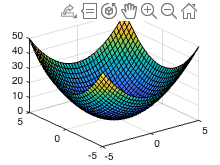

syms x1 x2;
f = x1^2 + x2^2;
fsurf(f)

grad_f = gradient(f, [x1, x2])

$$grad\_f = \left(\begin{array}{c} 2\,x_{1}\\ 2\,x_{2} \end{array}\right)$$

critical_points = solve(grad_f == 0, [x1, x2])

critical_points = struct with fields:
    x1: 0
    x2: 0


**Problem 1: Population Growth Model**

**Question 1**: Model the population growth using the logistic growth equation dP/dt=rP(1−P/K), where r=0.1per year and carrying capacity K=1000. Solve for P(t) with initial population P(0)=100 and plot the population over time.

% TODO


**Physics: Harmonic Oscillator**

**Problem 2: Harmonic Oscillator Motion**

**Question 2**: Solve the differential equation for a damped harmonic oscillator and plot the position over time. The system has mass m=1 kg, damping coefficient c=0.1 Ns/m, spring constant k=10 N/m, and initial conditions x(0)=1 m and x˙(0)=0 m/s.

% TODO
